# 实验二

## 时域采样

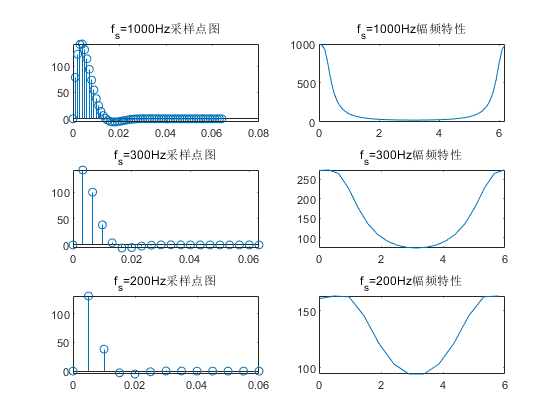

fs1 = 1000;
fs2 = 300;
fs3 = 200;
Tp = 64e-3;
t1 = 0:(1/fs1):Tp;
t2 = 0:(1/fs2):Tp;
t3 = 0:(1/fs3):Tp;
x1 = signal1(t1);
x2 = signal1(t2);
x3 = signal1(t3);
X1 = fft(x1);
X2 = fft(x2);
X3 = fft(x3);
w1 = 0:(2*pi/length(X1)):2*pi;
w2 = 0:(2*pi/length(X2)):2*pi;
w3 = 0:(2*pi/length(X3)):2*pi;
subplot(3, 2, 1);stem(t1, x1);title("f_s=1000Hz采样点图");
subplot(3, 2, 2);plot(w1(1:end-1), abs(X1)); title("f_s=1000Hz幅频特性");
subplot(3, 2, 3);stem(t2, x2);title("f_s=300Hz采样点图");
subplot(3, 2, 4);plot(w2(1:end-1), abs(X2)); title("f_s=300Hz幅频特性");
subplot(3, 2, 5);stem(t3, x3);title("f_s=200Hz采样点图");
subplot(3, 2, 6);plot(w3(1:end-1), abs(X3)); title("f_s=200Hz幅频特性");

## 频域采样

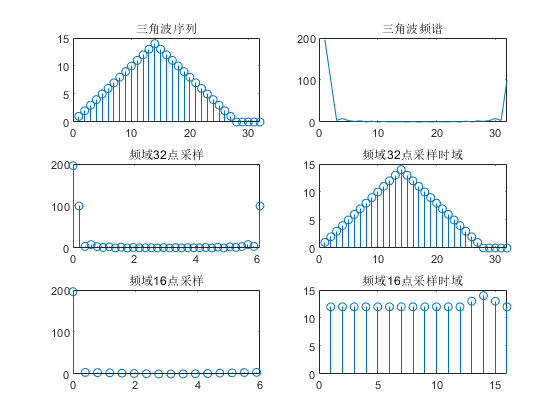

n = 0:31;
x = signal2(n);
X = fft(x);
figure;
X32 = X;
X16 = X(1:2:32);
x32 = ifft(X32);
x16 = ifft(X16);
w32 = 0:(2*pi/length(X32)):2*pi;
w16 = 0:(2*pi/length(X16)):2*pi;
subplot(3, 2, 1);stem(1:length(x), abs(x)); title("三角波序列");
subplot(3, 2, 2);plot(1:length(X), abs(X)); title("三角波频谱");
subplot(3, 2, 3);stem(w32(1:end-1), abs(X32)); title("频域32点采样");
subplot(3, 2, 4);stem(1:length(x32), abs(x32)); title("频域32点采样时域");
subplot(3, 2, 5);stem(w16(1:end-1), abs(X16)); title("频域16点采样");
subplot(3, 2, 6);stem(1:length(x16), abs(x16)); title("频域16点采样时域");